syms c kappa
KR = (2-3*c+c^2+(4*c-2*c^2)*cos(-kappa)+(c^2-c)*cos(-2*kappa))/2;
KI = ((4*c-2*c^2)*sin(-kappa)+(c^2-c)*sin(-2*kappa))/2;
KS = KI^2 + KR^2;
KS = simplify(expand(KS));
% KS = subs(KS,sin(2*kappa),cos(kappa)*sin(kappa)*2);
% KS = subs(KS,cos(2*kappa),cos(kappa)^2-sin(kappa)^2);
KS = (expand(KS))

$$KS = c^{4}\,{\cos\left(\kappa \right)}^{2}-2\,c^{4}\,\cos\left(\kappa \right)+c^{4}-4\,c^{3}\,{\cos\left(\kappa \right)}^{2}+8\,c^{3}\,\cos\left(\kappa \right)-4\,c^{3}+5\,c^{2}\,{\cos\left(\kappa \right)}^{2}-10\,c^{2}\,\cos\left(\kappa \right)+5\,c^{2}-2\,c\,{\cos\left(\kappa \right)}^{2}+4\,c\,\cos\left(\kappa \right)-2\,c+1$$

KS0 = subs(KS,kappa,0);
KSP = subs(KS,kappa,pi)

$$KSP = 4\,c^{4}-16\,c^{3}+20\,c^{2}-8\,c+1$$

DKS = diff(KS,1,kappa)

$$DKS = 10\,c^{2}\,\sin\left(\kappa \right)-8\,c^{3}\,\sin\left(\kappa \right)+2\,c^{4}\,\sin\left(\kappa \right)-4\,c\,\sin\left(\kappa \right)+4\,c\,\cos\left(\kappa \right)\,\sin\left(\kappa \right)-10\,c^{2}\,\cos\left(\kappa \right)\,\sin\left(\kappa \right)+8\,c^{3}\,\cos\left(\kappa \right)\,\sin\left(\kappa \right)-2\,c^{4}\,\cos\left(\kappa \right)\,\sin\left(\kappa \right)$$

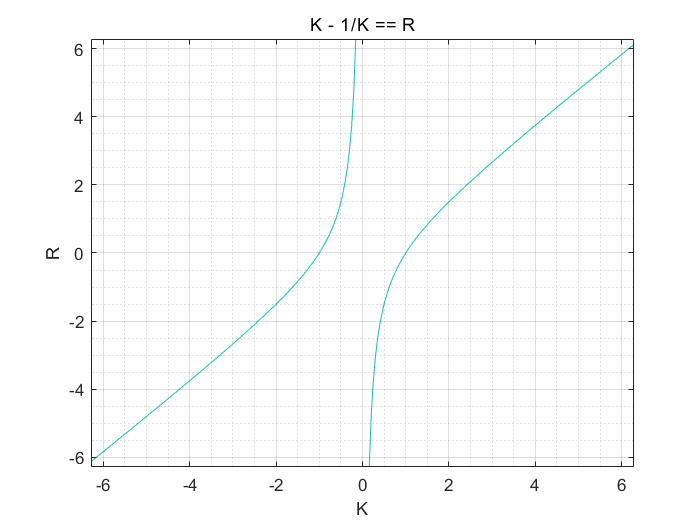

syms K R
ezplot(K-1/K==R)
grid on
grid minor